%% Seven-DoF Planar Robot Translation Control
% File: seven_dof_planar_robot_translation_control.m

%% Clean up
clear all;
close all;

%% Initialize DQ Robotics
include_namespace_dq

fprintf('7-DoF Planar Robot Translation Control\n\n');

7-DoF Planar Robot Translation Control




%% Create Robot Using DH Parameters
n_dof = 7;

% DH matrix: 5 rows x n_dof columns
DH_matrix = [zeros(1, n_dof);   % theta
             zeros(1, n_dof);   % d
             ones(1, n_dof);    % a = 1 for all links
             zeros(1, n_dof);   % alpha
             zeros(1, n_dof)];  % joint type (revolute)

robot = DQ_SerialManipulatorDH(DH_matrix, 'standard');
robot.name = '7-DoF Planar Robot';

fprintf('Robot: %s\n', robot.name);

Robot: 7-DoF Planar Robot


fprintf('DoFs: %d\n\n', robot.get_dim_configuration_space());

DoFs: 7




%% Initial Configuration
q_initial = (pi/8) * ones(7, 1);

fprintf('Initial configuration:\n');

Initial configuration:


for i = 1:7
    fprintf('  theta_%d(0) = %.4f rad (%.2f deg)\n', i, q_initial(i), rad2deg(q_initial(i)));
end

  theta_1(0) = 0.3927 rad (22.50 deg)
  theta_2(0) = 0.3927 rad (22.50 deg)
  theta_3(0) = 0.3927 rad (22.50 deg)
  theta_4(0) = 0.3927 rad (22.50 deg)
  theta_5(0) = 0.3927 rad (22.50 deg)
  theta_6(0) = 0.3927 rad (22.50 deg)
  theta_7(0) = 0.3927 rad (22.50 deg)



x_initial = robot.fkm(q_initial);
t_initial = translation(x_initial);
fprintf('\nInitial translation:\n');


Initial translation:


disp(t_initial);

  DQ with properties:

              q: [8×1 double]
    handle_axis: []
    handle_text: []
         isplot: []
              E: [1×1 DQ]
              i: [1×1 DQ]
              j: [1×1 DQ]
              k: [1×1 DQ]
      threshold: 1.0000e-12
             C8: [8×8 double]
             C4: [4×4 double]




%% Desired Translation
t_desired = DQ([0, 5, 2, 0]);

fprintf('Desired translation: t_d = 5*i + 2*j\n');

Desired translation: t_d = 5*i + 2*j


disp(t_desired);

  DQ with properties:

              q: [8×1 double]
    handle_axis: []
    handle_text: []
         isplot: []
              E: [1×1 DQ]
              i: [1×1 DQ]
              j: [1×1 DQ]
              k: [1×1 DQ]
      threshold: 1.0000e-12
             C8: [8×8 double]
             C4: [4×4 double]




%% Controller Setup
controller = DQ_PseudoinverseController(robot);
controller.set_gain(10);
controller.set_damping(0.01);
controller.set_control_objective(ControlObjective.Translation);

fprintf('Controller configured for translation control\n');

Controller configured for translation control


fprintf('  Gain: 10\n');

  Gain: 10


fprintf('  Damping: 0.01\n\n');

  Damping: 0.01




%% Simulation Parameters
dt = 0.001;
t_max = 5;
error_threshold = 1e-4;

time_vector = [];
error_vector = [];
q_vector = [];

q = q_initial;
t = 0;

fprintf('Starting control loop...\n');

Starting control loop...



%% Control Loop
while t < t_max
    % Current pose
    x_current = robot.fkm(q);
    t_current = translation(x_current);
    
    % Translation error
    t_error = t_desired - t_current;
    error_norm = norm(vec4(t_error));
    
    % Store data
    time_vector = [time_vector; t];
    error_vector = [error_vector; error_norm];
    q_vector = [q_vector, q];
    
    % Check convergence
    if error_norm < error_threshold
        fprintf('Converged at t = %.3f s\n', t);
        fprintf('Final error: %.6f\n', error_norm);
        break;
    end
    
    % Control signal
    u = controller.compute_setpoint_control_signal(q, vec4(t_desired));
    
    % Update
    q = q + u * dt;
    t = t + dt;
    
    % Progress
    if mod(round(t/dt), round(0.5/dt)) == 0
        fprintf('t = %.2f s, error = %.6f\n', t, error_norm);
    end
end

t = 0.50 s, error = 2.828486
t = 1.00 s, error = 2.828427
t = 1.50 s, error = 2.828427
t = 2.00 s, error = 2.828427
t = 2.50 s, error = 2.828427
t = 3.00 s, error = 2.828427
t = 3.50 s, error = 2.828427
t = 4.00 s, error = 2.828427
t = 4.50 s, error = 2.828427
t = 5.00 s, error = 2.828427



%% Final Results
fprintf('\nFinal Results:\n');


Final Results:


fprintf('Time: %.3f seconds\n', t);

Time: 5.000 seconds


fprintf('Final joint configuration:\n');

Final joint configuration:


for i = 1:7
    fprintf('  theta_%d = %.4f rad (%.2f deg)\n', i, q(i), rad2deg(q(i)));
end

  theta_1 = 0.0000 rad (0.00 deg)
  theta_2 = -0.0000 rad (-0.00 deg)
  theta_3 = 0.0000 rad (0.00 deg)
  theta_4 = -0.0000 rad (-0.00 deg)
  theta_5 = -0.0000 rad (-0.00 deg)
  theta_6 = 0.0000 rad (0.00 deg)
  theta_7 = 0.0000 rad (0.00 deg)



x_final = robot.fkm(q);
t_final = translation(x_final);
fprintf('\nFinal translation:\n');


Final translation:


disp(t_final);

  DQ with properties:

              q: [8×1 double]
    handle_axis: []
    handle_text: []
         isplot: []
              E: [1×1 DQ]
              i: [1×1 DQ]
              j: [1×1 DQ]
              k: [1×1 DQ]
      threshold: 1.0000e-12
             C8: [8×8 double]
             C4: [4×4 double]



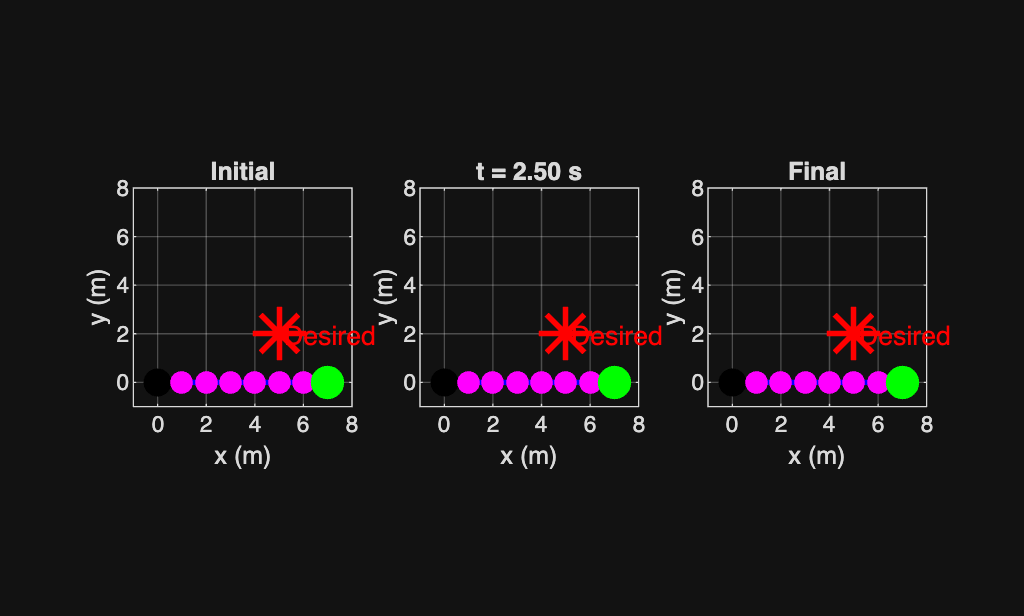


%% Visualization
figure('Name', '7-DoF Robot Translation');

% Plot configurations
subplot(1, 3, 1);
plot_robot(robot, q_initial, 'Initial', t_desired);

subplot(1, 3, 2);
mid_idx = round(size(q_vector, 2) / 2);
plot_robot(robot, q_vector(:, mid_idx), sprintf('t = %.2f s', time_vector(mid_idx)), t_desired);

subplot(1, 3, 3);
plot_robot(robot, q, 'Final', t_desired);

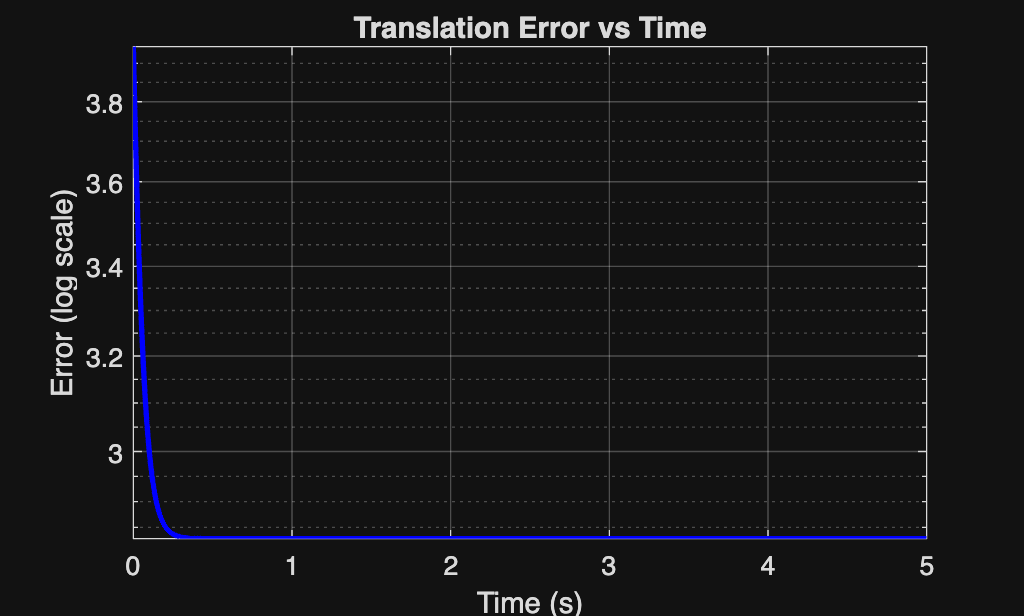


% Error plot
figure('Name', 'Translation Error');
semilogy(time_vector, error_vector, 'b-', 'LineWidth', 2);
grid on;
xlabel('Time (s)'); ylabel('Error (log scale)');
title('Translation Error vs Time');

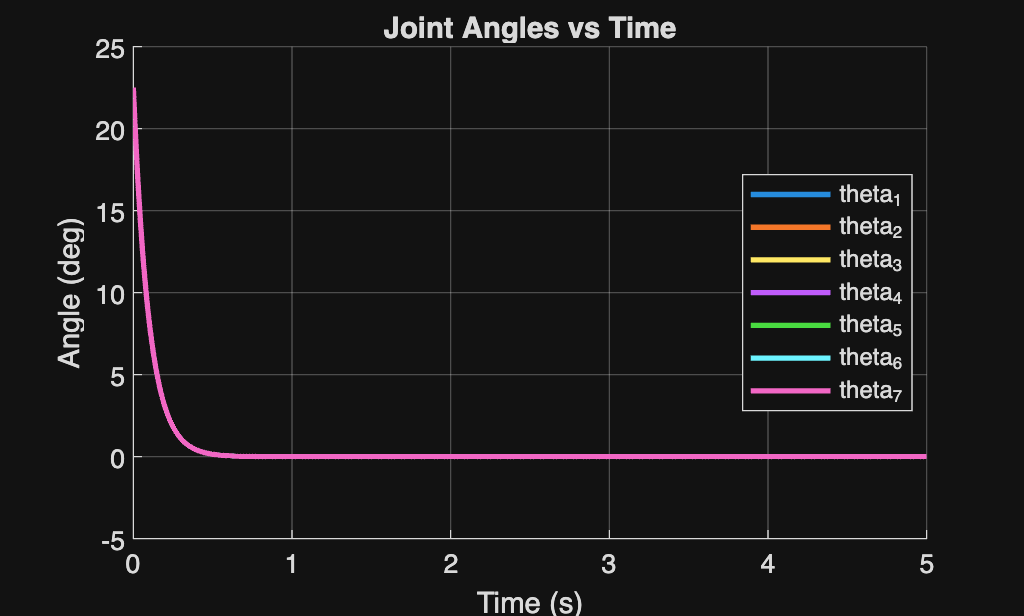


% Joint angles
figure('Name', 'Joint Angles');
colors = lines(7);
hold on;
for i = 1:7
    plot(time_vector, rad2deg(q_vector(i, :)), 'LineWidth', 2, 'Color', colors(i,:), ...
         'DisplayName', sprintf('theta_%d', i));
end
grid on;
xlabel('Time (s)'); ylabel('Angle (deg)');
title('Joint Angles vs Time');
legend('Location', 'best');
hold off;


fprintf('\nVisualization complete\n');


Visualization complete



%% Helper Function
function plot_robot(robot, q, title_str, t_desired)
    n = length(q);
    positions = zeros(n+1, 2);
    positions(1, :) = [0, 0];
    
    for i = 1:n
        x_i = robot.fkm(q, i);
        t_i = translation(x_i);
        t_vec = vec4(t_i);
        positions(i+1, :) = [t_vec(2), t_vec(3)];
    end
    
    plot(positions(:, 1), positions(:, 2), 'b-', 'LineWidth', 2);
    hold on;
    plot(positions(1, 1), positions(1, 2), 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'k');
    plot(positions(2:end-1, 1), positions(2:end-1, 2), 'mo', 'MarkerSize', 8, 'MarkerFaceColor', 'm');
    plot(positions(end, 1), positions(end, 2), 'go', 'MarkerSize', 12, 'MarkerFaceColor', 'g');
    
    t_des_vec = vec4(t_desired);
    plot(t_des_vec(2), t_des_vec(3), 'r*', 'MarkerSize', 20, 'LineWidth', 2);
    text(t_des_vec(2)+0.2, t_des_vec(3), 'Desired', 'FontSize', 10, 'Color', 'r');
    
    axis equal; grid on;
    xlabel('x (m)'); ylabel('y (m)');
    title(title_str);
    xlim([-1, 8]); ylim([-1, 8]);
    hold off;
end